## Feature Manipulation Experiment 7 

**In this notebook we will try to create our first Cubic Hyper-heuristic. This CHH will contain two solvers: **

**1) SHH5: A squared hyper-heuristic containing three solvers (HH1, HH2, and HH3, see previous experiments for descriptions)**

**2) LPA **

**The set of instances for testing will containg six instances, the first five will be I1-15 from experiment 6, and the sixth instance we will create in this notebook and name it I7: **

**I7: An Instance where LPA is the best performer and SHH5 does not solve correctly. **

**This notebook uses the next files: **

**FM_I1.mat, FM_I2.mat, FM_I3.mat, FM_I4.mat, FM_I5.mat, FM_I7.mat, LPT.mat, SPT.mat, MPA.mat, FM_HH1.mat, FM_HH1_multi.mat, FM_HH2.mat, FM_HH2_multi.mat, FM_HH3.mat, FM_HH3_multi.mat, FM_Exp6_Results.mat, FM_SHH5.mat**

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading instance I1, I2, I3, I4 and I5
load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")
load("FM_I4.mat")
load("FM_I5.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
I4.reset
I5.reset
InstanceSet={I1 I2 I3 I4 I5};

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('MPA_multi.mat')
load('LPA.mat')

%Loading HH1
load('FM_HH1.mat')
load('FM_HH1_multi.mat')

%Loading HH2
load('FM_HH2.mat')
load('FM_HH2_multi.mat')

%Loading HH3
load('FM_HH3.mat')
load('FM_HH3_multi.mat')

%Loading SHH5 
load("FM_SHH5.mat")

%Loading results from Exp6
load("FM_Exp6_Results.mat")

**INITIAL VISUALIZATION **

Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {[          42]}    {[     21.0665]}    {[     33.0

**These are the results from previous experiments, this is how all solvers perform at I1-I5. **

**NOW LET'S FIND INSTANCE 7 (WHERE LPA OUTPERFORMS SHH5)**

%Loading instance
load("FM_I7.mat")

%Adding instance to Instance Set
InstanceSet{6}=I7;

%solving set with all solvers 
solvedInstances_LPT=LPT.solveInstanceSet(InstanceSet);
solvedInstances_SPT=SPT.solveInstanceSet(InstanceSet);
solvedInstances_MPA=MPA.solveInstanceSet(InstanceSet);
solvedInstances_LPA=LPA.solveInstanceSet(InstanceSet);
solvedInstances_HH1=FM_HH1.solveInstanceSet(InstanceSet);
solvedInstances_HH2=FM_HH2.solveInstanceSet(InstanceSet);
solvedInstances_HH3=FM_HH3.solveInstanceSet(InstanceSet);
solvedInstances_SHH5=FM_SHH5.solveInstanceSet(InstanceSet);

%Adding results of instance 7
Results{1,7}='Instance 7';
Results{2,7}=solvedInstances_LPT{6}.solution.makespan;
Results{3,7}=solvedInstances_SPT{6}.solution.makespan;
Results{4,7}=solvedInstances_MPA{6}.solution.makespan;
Results{5,7}=solvedInstances_LPA{6}.solution.makespan;
Results{6,7}=solvedInstances_HH1{6}.solution.makespan;
Results{7,7}=solvedInstances_HH2{6}.solution.makespan;
Results{8,7}=solvedInstances_HH3{6}.solution.makespan;
Results{9,7}=solvedInstances_SHH5{6}.solution.makespan;
Results

Results = 9×7 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}    {'Instance 7'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}    {[   48.9464]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}    {[   28.9472]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}    {[   48.9464]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}    {[   48.9465]}
    {'HH3'     }    {[          49]}    {[     41.0665]}  

**We got our instance, only LPA performs well when solving it. Now let's create our CHH model: **

**CREATING A CHH**

%First let's make a multi version of LPA
props = struct('nbLayers',1,'nbRules',1, 'selectedSolvers',4, 'selectedFeatures', [1]); %parameters for LPA in the multi form
LPA_multi=ruleBasedSelectionHHMulti(props); %creating LPA with multiHH class


%Now the CHH
props = struct('nbLayers',3,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[FM_SHH5 LPA_multi],'selectedFeatures', [1]);
FM_CHH1=ruleBasedSelectionHHMulti(props)

FM_CHH1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(sr

**LET'S TRY THE CHH**

%solving with CHH and updating results
solvedInstances_CHH1=FM_CHH1.solveInstanceSet(InstanceSet);
Results{10,1}='CHH1';
Results{10,2}=solvedInstances_CHH1{1}.solution.makespan;
Results{10,3}=solvedInstances_CHH1{2}.solution.makespan;
Results{10,4}=solvedInstances_CHH1{3}.solution.makespan;
Results{10,5}=solvedInstances_CHH1{4}.solution.makespan;
Results{10,6}=solvedInstances_CHH1{5}.solution.makespan;
Results{10,7}=solvedInstances_CHH1{6}.solution.makespan;
Results

Results = 10×7 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}    {'Instance 7'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}    {[   48.9464]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}    {[   28.9472]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}    {[   48.9464]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}    {[   48.9465]}
    {'HH3'     }    {[          49]}    {[     41.0665]} 

**It is very unlikely for the CHH to perform well as the initial model is random. Let's look a the instances' features to create our own model:**

**Looking at the instances' features**

I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


I4.getFeatureVector([1 2 3 4 5])

ans =     0.2544    0.3334    0.3767    0.6667    0.3333


I5.getFeatureVector([1 2 3 4 5])

ans =          0    0.4923    0.4015    0.2963    0.0417


I7.getFeatureVector([1 2 3 4 5])

ans =     0.0973    0.1164    0.3128    0.4074    0.1250


**Let's try using the second feature**

%Updating to the second feature
props = struct('nbLayers',3,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[FM_SHH5 LPA_multi],'selectedFeatures', [2]);
FM_CHH1=ruleBasedSelectionHHMulti(props);


%Creating a model for the CHH
CHH1_model=[0.2 1; 0.1 2];
FM_CHH1.value=CHH1_model;


%solving with CHH and updating results
solvedInstances_CHH1=FM_CHH1.solveInstanceSet(InstanceSet);
Results{10,1}='CHH1';
Results{10,2}=solvedInstances_CHH1{1}.solution.makespan;
Results{10,3}=solvedInstances_CHH1{2}.solution.makespan;
Results{10,4}=solvedInstances_CHH1{3}.solution.makespan;
Results{10,5}=solvedInstances_CHH1{4}.solution.makespan;
Results{10,6}=solvedInstances_CHH1{5}.solution.makespan;
Results{10,7}=solvedInstances_CHH1{6}.solution.makespan;
Results

Results = 10×7 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}    {'Instance 7'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}    {[   48.9464]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}    {[   28.9472]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}    {[   48.9464]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}    {[   48.9465]}
    {'HH3'     }    {[          49]}    {[     41.0665]} 

**We are almost there, for solving I3 we might just need another rule: **


%Creating a model for the CHH
CHH1_model=[0.15 1; 0.1 1 ;0.11 2];
FM_CHH1.value=CHH1_model;


%solving with CHH and updating results
solvedInstances_CHH1=FM_CHH1.solveInstanceSet(InstanceSet);
Results{10,1}='CHH1';
Results{10,2}=solvedInstances_CHH1{1}.solution.makespan;
Results{10,3}=solvedInstances_CHH1{2}.solution.makespan;
Results{10,4}=solvedInstances_CHH1{3}.solution.makespan;
Results{10,5}=solvedInstances_CHH1{4}.solution.makespan;
Results{10,6}=solvedInstances_CHH1{5}.solution.makespan;
Results{10,7}=solvedInstances_CHH1{6}.solution.makespan;
Results

Results = 10×7 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}    {'Instance 7'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}    {[   48.9464]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}    {[   28.9472]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}    {[   48.9464]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}    {[   48.9465]}
    {'HH3'     }    {[          49]}    {[     41.0665]} 

**We solved I3, now for solving instance 7 we might need another feature: **

%Updating to using feature 2 and 3
props = struct('nbLayers',3,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[FM_SHH5 LPA_multi],'selectedFeatures', [2 3]);
FM_CHH1=ruleBasedSelectionHHMulti(props);



%Creating a model for the CHH with 3 rules and 2 features 
CHH1_model=[0.15 0.4 1; 0.1 0.2 1 ;0.11 0.31 2];
FM_CHH1.value=CHH1_model;

%solving with CHH and updating results
solvedInstances_CHH1=FM_CHH1.solveInstanceSet(InstanceSet);
Results{10,1}='CHH1';
Results{10,2}=solvedInstances_CHH1{1}.solution.makespan;
Results{10,3}=solvedInstances_CHH1{2}.solution.makespan;
Results{10,4}=solvedInstances_CHH1{3}.solution.makespan;
Results{10,5}=solvedInstances_CHH1{4}.solution.makespan;
Results{10,6}=solvedInstances_CHH1{5}.solution.makespan;
Results{10,7}=solvedInstances_CHH1{6}.solution.makespan;
Results

Results = 10×7 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}    {'Instance 7'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}    {[   48.9464]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}    {[   48.9463]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}    {[   28.9472]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}    {[   48.9464]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}    {[   48.9465]}
    {'HH3'     }    {[          49]}    {[     41.0665]} 

**We did it! We made our first Cubic Hyper-Heuristic! **

%FM_CHH1.plotFeatureMap(InstanceSet,"full",struct('features',[1 1]),true,6)

**Let's look at the model: **

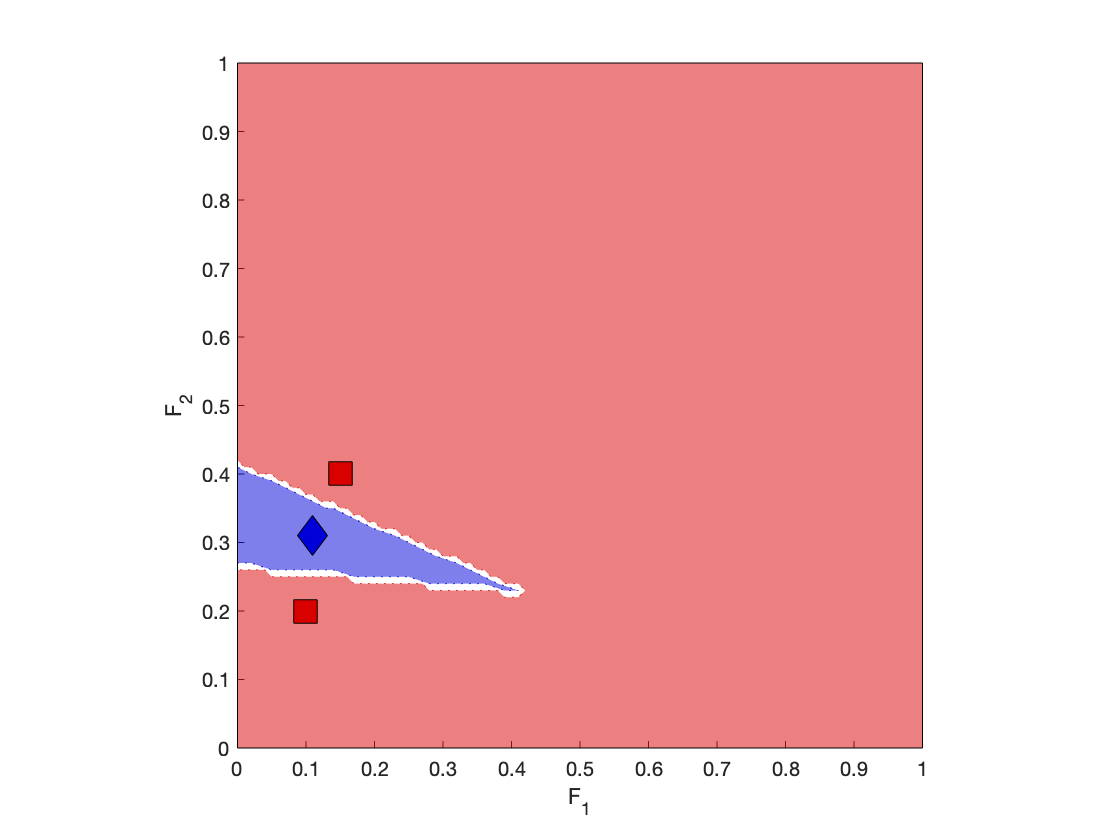

ans =     0.9649    0.0283


FM_CHH1.plotZones(0:0.01:1,1,[1 2],1)

**It looks like a very cool model, only a small portion is intended to use LPA which is useful to solve instance 7, the rest uses SHH5 which solves the rest of the instances. **

**Saving files**

save('FM_CHH1','FM_CHH1')
save('FM_Exp7_Results','Results')
save('LPA_multi','LPA_multi')
